# Circular Restricted Three-Body Problem with the Astrodynamics Toolbox

This script is intended to be converted into a MATLAB Live Script (.mlx). It reuses the existing CR3BP functions already implemented in the toolbox to provide an interactive introduction to:

- CR3BP equations of motion and nondimensionalisation

- Lagrange points and effective potential

- Jacobi constant and zero-velocity curves

- propagation in the rotating frame

- variational equations and STM propagation

- planar Lyapunov differential correction

- generic single shooting and multiple shooting

- halo-family pseudo-arclength continuation from JPL seeds

- monodromy matrix, stability indices, and invariant manifolds

- Poincare sections

The guiding principle is the same as in the classical live script: explain the theory carefully, but reuse the toolbox functions for all actual computations.

## Initialisation

clear; clc; close all;

## Paths and toolbox setup

scriptPath = matlab.desktop.editor.getActiveFilename;
scriptDir  = fileparts(scriptPath);
repoRoot   = fileparts(scriptDir);

run(fullfile(repoRoot, 'startup.m'));

astroToolbox path added.


## Plot styling

clr.primary   = [0.00 0.45 0.74];
clr.secondary = [0.85 0.33 0.10];
clr.green     = [0.47 0.67 0.19];
clr.purple    = [0.49 0.18 0.56];
clr.gray      = [0.25 0.25 0.25];
clr.light     = [0.85 0.85 0.85];
clr.family1   = [0.00 0.25 0.90];
clr.family2   = [0.00 0.60 0.30];
clr.manU      = [0.85 0.20 0.20];
clr.manS      = [0.10 0.55 0.20];

## Live Script controls

In the final .mlx version, convert the variables in this section into Live Editor controls such as sliders, dropdown menus, and checkboxes.

systemName       = 'Earth-Moon';   
zvcJacobiOffset  = 0.01;          
planarDx         = 0.01;         
planarVyGuess    = 0.1;           
nMembersHalo     = 200;             
dsHalo           = 0.0005;           
showManifolds    = true;           
showPoincare     = true;           

## Introduction

The Circular Restricted Three-Body Problem (CR3BP) models the motion of a particle of negligible mass under the gravitational attraction of two primaries that move on circular orbits about their barycentre.

In the rotating synodic frame, the primaries are fixed at


$$(-\mu,\;0,\;0), \qquad (1-\mu,\;0,\;0)$$


where the mass parameter is


$$\mu = \frac{m_2}{m_1+m_2}$$


Distances are normalised by the distance between the primaries, masses by the total mass, and time by the inverse mean motion. In these units the mean motion is 1.

Let the state in the rotating frame be


$$\mathbf{x} = \left[\begin{array}{c}
x \\
y \\
z \\
\dot{x} \\
\dot{y} \\
\dot{z}
\end{array}\right]$$


Then the equations of motion are


$$\ddot{x} - 2\dot{y} = \frac{\partial \Omega}{\partial x}$$



$$\ddot{y} + 2\dot{x} = \frac{\partial \Omega}{\partial y}$$



$$\ddot{z} = \frac{\partial \Omega}{\partial z}$$


where the effective potential is


$$\Omega(x,y,z)
 = \frac{1}{2}(x^2+y^2)
 + \frac{1-\mu}{r_1}
 + \frac{\mu}{r_2}$$


with


$$r_1 = \sqrt{(x+\mu)^2+y^2+z^2}, \qquad
 r_2 = \sqrt{(x-1+\mu)^2+y^2+z^2}$$


This formulation reveals the equilibrium points, periodic orbits, stable and unstable manifolds, and transport structure of the problem very clearly.

## System selection

switch lower(systemName)
    case {'earth-moon','earth moon'}
        mu = 0.012150585609624;
        systemLabel = 'Earth-Moon CR3BP';
    case {'sun-earth','sun earth'}
        mu = 3.040423398e-6;
        systemLabel = 'Sun-Earth CR3BP';
    otherwise
        error('Unknown system selection.');
end

fprintf('Selected system: %s\n', systemLabel);

Selected system: Earth-Moon CR3BP


fprintf('Mass parameter mu = %.15f\n', mu);

Mass parameter mu = 0.012150585609624


## Lagrange points

The equilibrium points satisfy


$$\nabla \Omega = 0$$


There are five such points:

- $L_1$, $L_2$, and $L_3$ are collinear

- $L_4$ and $L_5$ are equilateral

The collinear points are linearly unstable and are the source of many important periodic-orbit families such as Lyapunov and halo orbits.

L = astro.cr3bp.lagrangePoints(mu);

disp('Lagrange points:');

Lagrange points:


disp(L);

    L1: [3×1 double]
    L2: [3×1 double]
    L3: [3×1 double]
    L4: [3×1 double]
    L5: [3×1 double]



## Plot primaries and Lagrange points

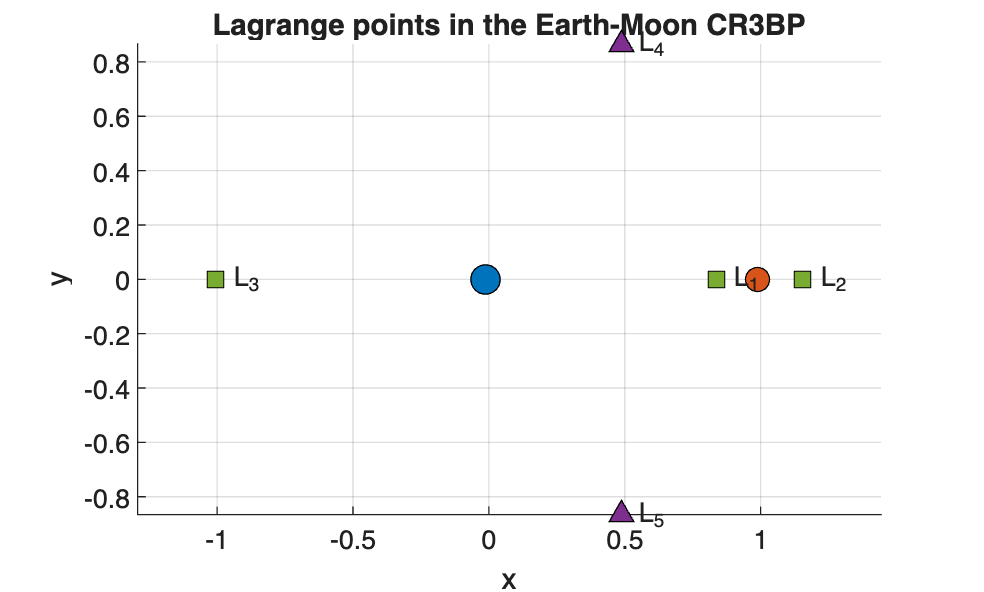

figure('Color','w');
hold on; grid on; axis equal;

plot(-mu, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot(1-mu, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');

plot(L.L1(1), L.L1(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
plot(L.L2(1), L.L2(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
plot(L.L3(1), L.L3(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
plot(L.L4(1), L.L4(2), '^', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.purple, 'MarkerEdgeColor', 'k');
plot(L.L5(1), L.L5(2), '^', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.purple, 'MarkerEdgeColor', 'k');

text(L.L1(1), L.L1(2), '  L_1');
text(L.L2(1), L.L2(2), '  L_2');
text(L.L3(1), L.L3(2), '  L_3');
text(L.L4(1), L.L4(2), '  L_4');
text(L.L5(1), L.L5(2), '  L_5');

xlabel('x');
ylabel('y');
title(['Lagrange points in the ' systemLabel]);

## Jacobi constant and zero-velocity curves

The CR3BP admits the Jacobi integral


$$C = 2\Omega(x,y,z) - \left(\dot{x}^2+\dot{y}^2+\dot{z}^2\right)$$


Therefore


$$\dot{x}^2+\dot{y}^2+\dot{z}^2 = 2\Omega - C$$


and motion is only possible where $2\Omega - C \ge 0$.

The equality


$$2\Omega(x,y,0) - C = 0$$


defines the planar zero-velocity curves, which bound the forbidden regions.

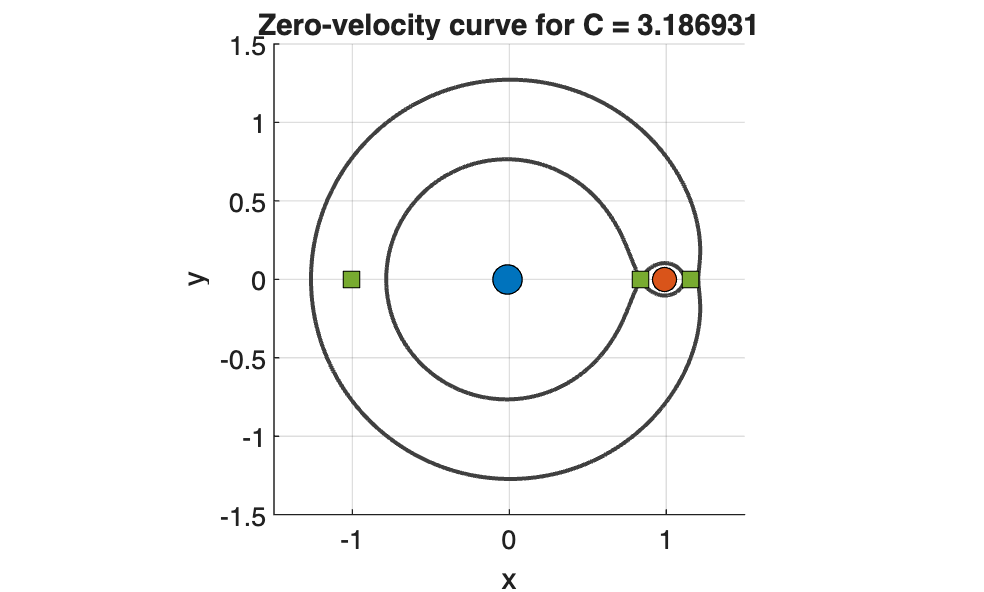

x0_demo = [L.L1(1)-zvcJacobiOffset; 0; 0; 0; 0.05; 0];
C_example = astro.cr3bp.jacobiConstant(x0_demo, mu);

xGrid = linspace(-1.5, 1.5, 500);
yGrid = linspace(-1.5, 1.5, 500);
[X, Y] = meshgrid(xGrid, yGrid);

OmegaGrid = arrayfun(@(x,y) astro.cr3bp.effectivePotential(x, y, 0, mu), X, Y);
ZVC = 2*OmegaGrid - C_example;

figure('Color','w');
hold on; axis equal; grid on;
contour(X, Y, ZVC, [0 0], 'Color', clr.gray, 'LineWidth', 1.5);

plot(-mu, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot(1-mu, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');

plot(L.L1(1), L.L1(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
plot(L.L2(1), L.L2(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
plot(L.L3(1), L.L3(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');

xlabel('x');
ylabel('y');
title(sprintf('Zero-velocity curve for C = %.6f', C_example));

## Sample propagation in the rotating frame

A first propagation helps visualise the rotating-frame geometry before moving on to periodic orbit correction.

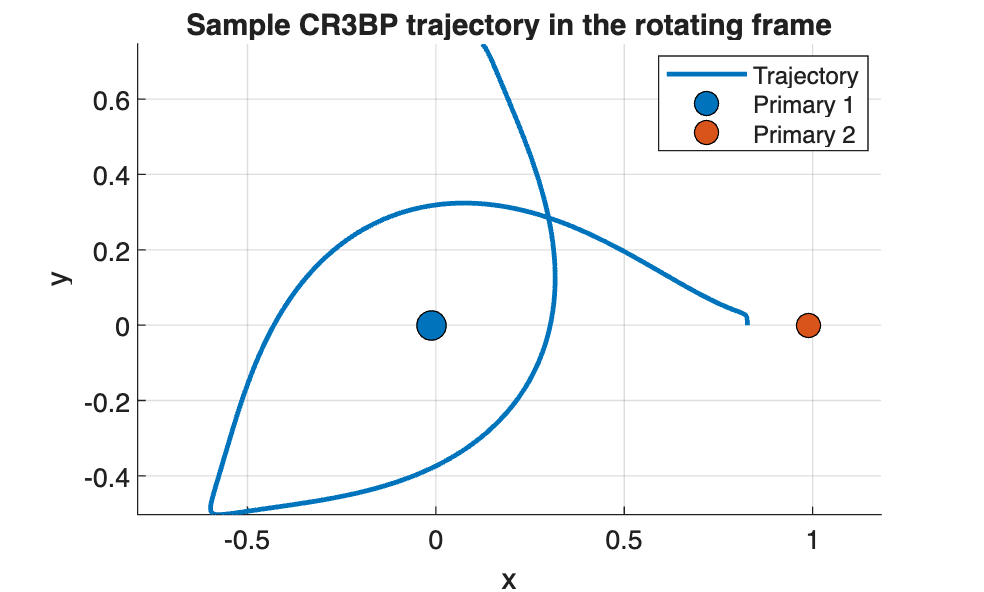

optsCR3BP = struct();
optsCR3BP.RelTol = 1e-12;
optsCR3BP.AbsTol = 1e-12;
optsCR3BP.Solver = 'ode113';

outDemo = astro.propagators.propagate( ...
    @(t,x) astro.cr3bp.eomCR3BP(t, x, mu), ...
    [0 6], x0_demo, optsCR3BP);

figure('Color','w');
hold on; grid on; axis equal;
plot3(outDemo.x(:,1), outDemo.x(:,2), outDemo.x(:,3), ...
    'Color', clr.primary, 'LineWidth', 1.8);
plot3(-mu, 0, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot3(1-mu, 0, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');
xlabel('x');
ylabel('y');
zlabel('z');
title('Sample CR3BP trajectory in the rotating frame');
legend('Trajectory', 'Primary 1', 'Primary 2', 'Location', 'best');

## Variational equations and STM propagation

If $\Phi(t,t_0)$ is the state transition matrix, then


$$\dot{\Phi}(t,t_0)=A(t)\Phi(t,t_0), \qquad \Phi(t_0,t_0)=I$$


where


$$A(t)=\frac{\partial f}{\partial x}\Big|_{x(t)}$$


The variational equations are essential for differential correction, stability analysis, and manifold construction.

outSTM = astro.cr3bp.propagateWithSTM(x0_demo, [0 6], mu);

disp('STM propagation output:');

STM propagation output:


disp(outSTM);

           t: [664×1 double]
        Yaug: [664×42 double]
           x: [664×6 double]
    PhiFinal: [6×6 double]



## Planar Lyapunov differential correction

A planar Lyapunov orbit uses the initial state


$$X_0 = [x_0,\;0,\;0,\;0,\;v_{y0},\;0]^T$$


and your corrector adjusts $v_{y0}$ so that, at the first nontrivial $y=0$ symmetry crossing, the residual condition


$$\dot{x}(t_{1/2}) = 0$$


is satisfied. The final period is then


$$T = 2t_{1/2}$$


This is a specialised single-shooting correction scheme for planar Lyapunov orbits.

x0_planar = L.L1(1) - planarDx;
vy0_planar = planarVyGuess;

solPlanar = astro.cr3bp.differentialCorrectionPlanarLyapunov( ...
    x0_planar, vy0_planar, mu, 30, 1e-10);

disp('Planar Lyapunov correction result:');

Planar Lyapunov correction result:


disp(solPlanar);

            x0: 0.8269
           vy0: 0.0948
        state0: [6×1 double]
    halfPeriod: 2.1943
        period: 4.3886
     converged: 1
    iterations: 6
     stateHalf: [6×1 double]
    trajectory: [1×1 struct]



## Plot corrected planar Lyapunov orbit

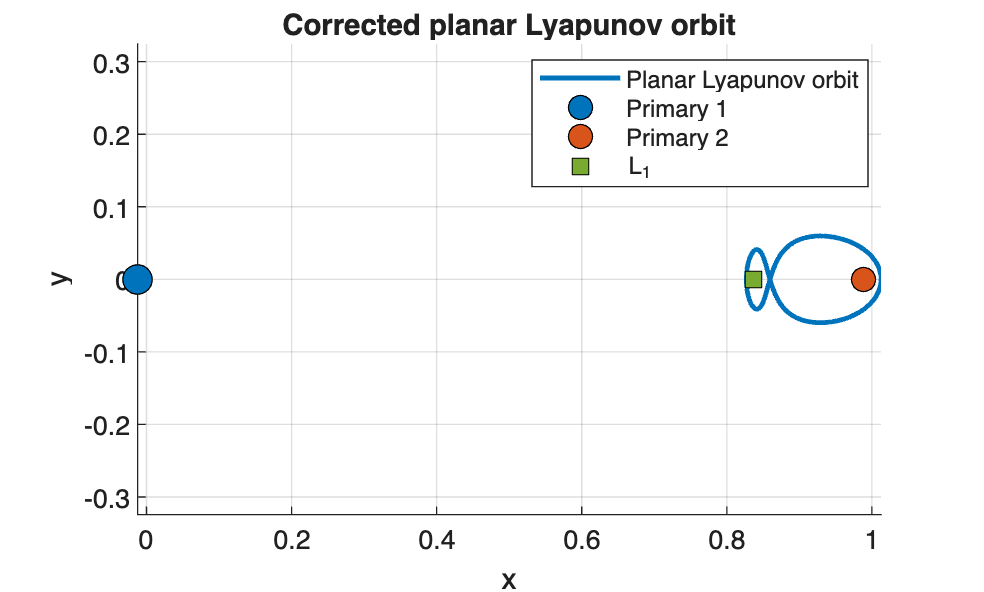

outPlanar = astro.propagators.propagate( ...
    @(t,x) astro.cr3bp.eomCR3BP(t, x, mu), ...
    [0 solPlanar.period], solPlanar.state0, optsCR3BP);

figure('Color','w');
hold on; grid on; axis equal;
plot(outPlanar.x(:,1), outPlanar.x(:,2), 'Color', clr.primary, 'LineWidth', 1.8);
plot(-mu, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot(1-mu, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');
plot(L.L1(1), L.L1(2), 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');
xlabel('x');
ylabel('y');
title('Corrected planar Lyapunov orbit');
legend('Planar Lyapunov orbit', 'Primary 1', 'Primary 2', 'L_1', 'Location', 'best');

## Generic single shooting

In generic single shooting, one solves


$$F = X(t_f)-X_0 = 0$$


by correcting selected initial-state components and possibly the final time.

The Newton step is based on the STM and, if the final time is free, on the final vector field contribution.

freeIdx = [2 3 4 5 6];
isTfFree = true;

solSingle = astro.cr3bp.singleShootingCorrector( ...
    solPlanar.state0, solPlanar.period, mu, freeIdx, isTfFree, 20, 1e-10);

Single shooting iter  1: ||F|| = 6.683e-11



disp('Generic single shooting correction result:');

Generic single shooting correction result:


disp(solSingle);

            x0: [6×1 double]
            tf: 4.3886
     converged: 1
    iterations: 1
      residual: 6.6827e-11
    trajectory: [1×1 struct]
      PhiFinal: [6×6 double]



## Multiple shooting

Multiple shooting divides the orbit into several trajectory segments with node states


$$X_0^{(1)}, X_0^{(2)}, \dots, X_0^{(N)}$$


Each segment is propagated independently, and continuity defects are enforced:


$$X^{(i)}(\Delta t_i)-X_0^{(i+1)} = 0$$


together with periodic closure on the last segment.

The method is usually more robust than single shooting for unstable orbits because local defects are corrected segment by segment.

Nnodes = 4;
tNodes = linspace(0, solPlanar.period, Nnodes+1);
Xnodes = zeros(6, Nnodes);

for k = 1:Nnodes
    idx = max(1, round((tNodes(k)/solPlanar.period) * (size(outPlanar.x,1)-1)) + 1);
    Xnodes(:,k) = outPlanar.x(idx,:).';
end

dtSeg = solPlanar.period / Nnodes;

solMulti = astro.cr3bp.multipleShootingCorrector( ...
    Xnodes, dtSeg, mu, 20, 1e-10);

Multiple shooting iter  1: ||F|| = 9.717e-01
Multiple shooting iter  2: ||F|| = 2.464e+00
Multiple shooting iter  3: ||F|| = 1.286e+00


Multiple shooting iter  4: ||F|| = 3.778e+02


Multiple shooting iter  5: ||F|| = 1.991e+02


Multiple shooting iter  6: ||F|| = 9.345e+01
Multiple shooting iter  7: ||F|| = 1.442e+00
Multiple shooting iter  8: ||F|| = 4.860e+00
Multiple shooting iter  9: ||F|| = 2.140e+00
Multiple shooting iter 10: ||F|| = 3.175e+00
Multiple shooting iter 11: ||F|| = 8.828e+01
Multiple shooting iter 12: ||F|| = 2.775e+00
Multiple shooting iter 13: ||F|| = 2.672e+00
Multiple shooting iter 14: ||F|| = 4.993e+00
Multiple shooting iter 15: ||F|| = 3.111e+00
Multiple shooting iter 16: ||F|| = 9.179e+00
Multiple shooting iter 17: ||F|| = 3.472e+00
Multiple shooting iter 18: ||F|| = 1.401e+00
Multiple shooting iter 19: ||F|| = 2.744e+00
Multiple shooting iter 20: ||F|| = 1.117e+00



disp('Multiple shooting correction result:');

Multiple shooting correction result:


disp(solMulti);

        Xnodes: [6×4 double]
         dtSeg: [1.0972 1.0972 1.0972 1.0972]
     converged: 0
    iterations: 20
      residual: 1.1173
      segments: {4×1 cell}



## Halo-family pseudo-arclength continuation from JPL seeds

Halo correction is much more sensitive to the initial seed than the planar case. Instead of using an arbitrary seed, the live script reuses the same robust workflow already used in your examples:

1. query two nearby JPL halo seeds 2. parse them into local seed structs 3. continue the family with pseudo-arclength continuation

In pseudo-arclength continuation, if $\mathbf{u}_k$ is the current family member and $\tau_k$ is the tangent, the predictor is


$$\mathbf{u}_{k+1}^{pred} = \mathbf{u}_k + \Delta s\,\tau_k$$


and the corrector solves the periodic-orbit constraints together with


$$(\mathbf{u}-\mathbf{u}_{k+1}^{pred})^T\tau_k = 0$$


which allows the continuation to pass folds and turning points.

fprintf('\n');
fprintf('============================================================\n');

fprintf('Halo Family Continuation Demo\n');

Halo Family Continuation Demo


fprintf('============================================================\n');


dataJPL = astro.cr3bp.queryJPLPeriodicOrbits( ...
    'sys', 'earth-moon', ...
    'family', 'halo', ...
    'libr', 1, ...
    'branch', 'N');

seed1 = astro.cr3bp.parseJPLPeriodicOrbit(dataJPL, 1);
seed2 = astro.cr3bp.parseJPLPeriodicOrbit(dataJPL, 2);

muHalo = seed1.mu;

fprintf('\nSeed 1:\n');


Seed 1:


fprintf('  x0     = %.12f\n', seed1.state(1));

  x0     = -0.414561848031


fprintf('  z0     = %.12f\n', seed1.state(3));

  z0     = 0.907531204333


fprintf('  vy0    = %.12f\n', seed1.state(5));

  vy0    = 1.407614546014


fprintf('  Period = %.12f TU\n', seed1.period);

  Period = 3.123314392276 TU



fprintf('\nSeed 2:\n');


Seed 2:


fprintf('  x0     = %.12f\n', seed2.state(1));

  x0     = -0.414219826614


fprintf('  z0     = %.12f\n', seed2.state(3));

  z0     = 0.907686296377


fprintf('  vy0    = %.12f\n', seed2.state(5));

  vy0    = 1.407270095058


fprintf('  Period = %.12f TU\n', seed2.period);

  Period = 3.123311261055 TU



family = astro.cr3bp.continueHaloPseudoArc(seed1, seed2, nMembersHalo, dsHalo, muHalo);


Starting halo pseudo-arclength continuation...
Stored seed members 1 and 2

Attempting halo family member 3
  Retry 1 with ds = 5.000e-04
    Halo pseudo-arc iter  1: ||F|| = 9.913e-05
    Halo pseudo-arc iter  2: ||F|| = 1.253e-08
    Halo pseudo-arc iter  3: ||F|| = 3.522e-12
  Stored halo family member 3
    x0         = -0.413884207902
    z0         = 0.907838330213
    vy0        = 1.406932095890
    halfPeriod = 1.561654088748 TU
    C          = 0.196512883595

Attempting halo family member 4
  Retry 1 with ds = 5.000e-04
    Halo pseudo-arc iter  1: ||F|| = 9.822e-05
    Halo pseudo-arc iter  2: ||F|| = 1.231e-08
    Halo pseudo-arc iter  3: ||F|| = 6.163e-12
  Stored halo family member 4
    x0         = -0.413548556307
    z0         = 0.907990225617
    vy0        = 1.406594067164
    halfPeriod = 1.561652541396 TU
    C          = 0.197181638598

Attempting halo family member 5
  Retry 1 with ds = 5.000e-04
    Halo pseudo-arc iter  1: ||F|| = 9.825e-05
    Halo pseudo-ar


nFam = numel(family);
if nFam < 2
    error('Too few halo family members generated.');
end

Cvals = [family.C];
Tvals = [family.period];
z0vals = arrayfun(@(s) s.u(2), family);

fprintf('\nHalo family summary:\n');


Halo family summary:


fprintf('  Stored members : %d\n', nFam);

  Stored members : 200


fprintf('  C range        : [%.12f, %.12f]\n', min(Cvals), max(Cvals));

  C range        : [0.195162730858, 0.329334007895]


fprintf('  T range [TU]   : [%.12f, %.12f]\n', min(Tvals), max(Tvals));

  T range [TU]   : [3.122488768660, 3.123314392276]


fprintf('  z0 range       : [%.12f, %.12f]\n', min(z0vals), max(z0vals));

  z0 range       : [0.907531204333, 0.935114632710]



Lhalo = astro.cr3bp.lagrangePoints(muHalo);

## 3D halo family plot

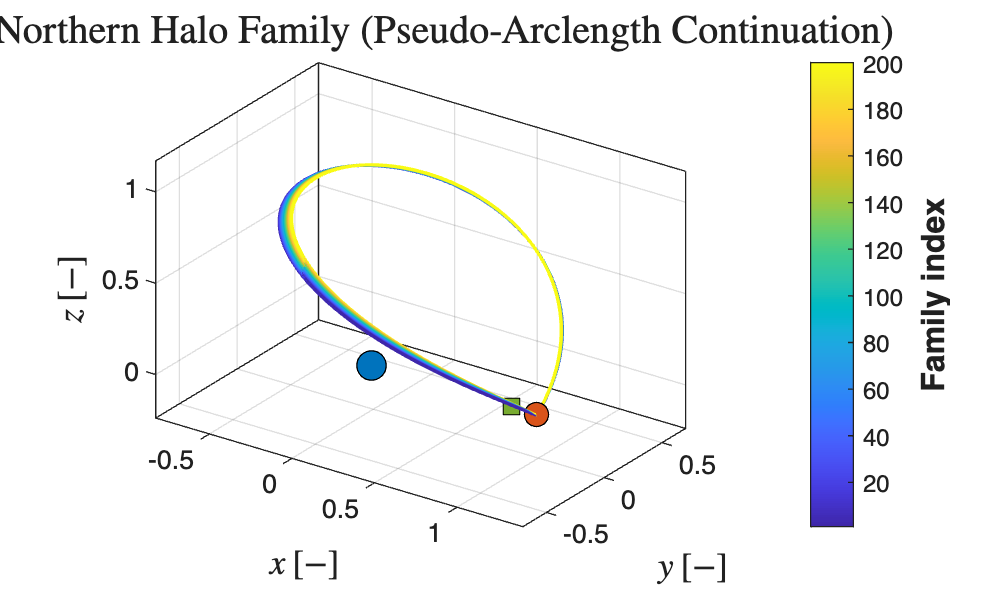

figure('Color','w');
hold on; grid on; box on; axis equal;

cmap = parula(max(nFam,16));

for k = 1:nFam
    Xfam = family(k).traj;
    plot3(Xfam(:,1), Xfam(:,2), Xfam(:,3), 'Color', cmap(k,:), 'LineWidth', 1.2);
end

plot3(-muHalo, 0, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot3(1-muHalo, 0, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');
plot3(Lhalo.L1(1), Lhalo.L1(2), 0, 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');

xlabel('$x~[-]$', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('$y~[-]$', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
zlabel('$z~[-]$', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
title('$L_1$ Northern Halo Family (Pseudo-Arclength Continuation)', ...
    'Interpreter', 'latex', 'FontSize', 15, 'FontWeight', 'bold');
view(35, 25);

colormap(cmap);
cb = colorbar;
ylabel(cb, 'Family index', 'FontSize', 12, 'FontWeight', 'bold');
clim([1 max(nFam,2)]);

## x-z projection of the halo family

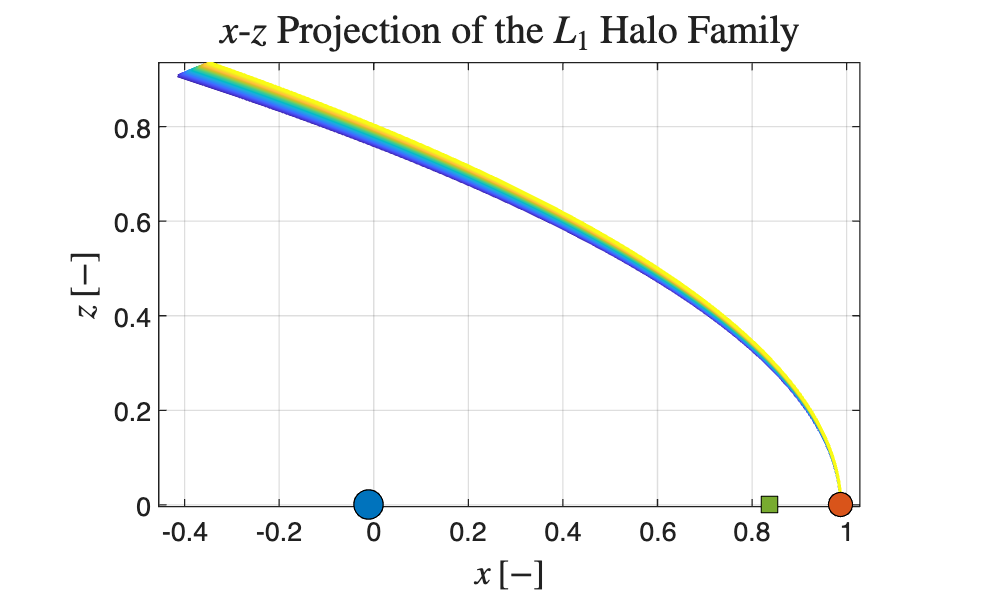

figure('Color','w');
hold on; grid on; box on; axis equal;

for k = 1:nFam
    Xfam = family(k).traj;
    plot(Xfam(:,1), Xfam(:,3), 'Color', cmap(k,:), 'LineWidth', 1.2);
end

plot(-muHalo, 0, 'o', 'MarkerSize', 11, ...
    'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
plot(1-muHalo, 0, 'o', 'MarkerSize', 9, ...
    'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');
plot(Lhalo.L1(1), 0, 's', 'MarkerSize', 8, ...
    'MarkerFaceColor', clr.green, 'MarkerEdgeColor', 'k');

xlabel('$x~[-]$', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('$z~[-]$', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');
title('$x$-$z$ Projection of the $L_1$ Halo Family', ...
    'Interpreter', 'latex', 'FontSize', 15, 'FontWeight', 'bold');

## Jacobi constant and period trends along the halo family

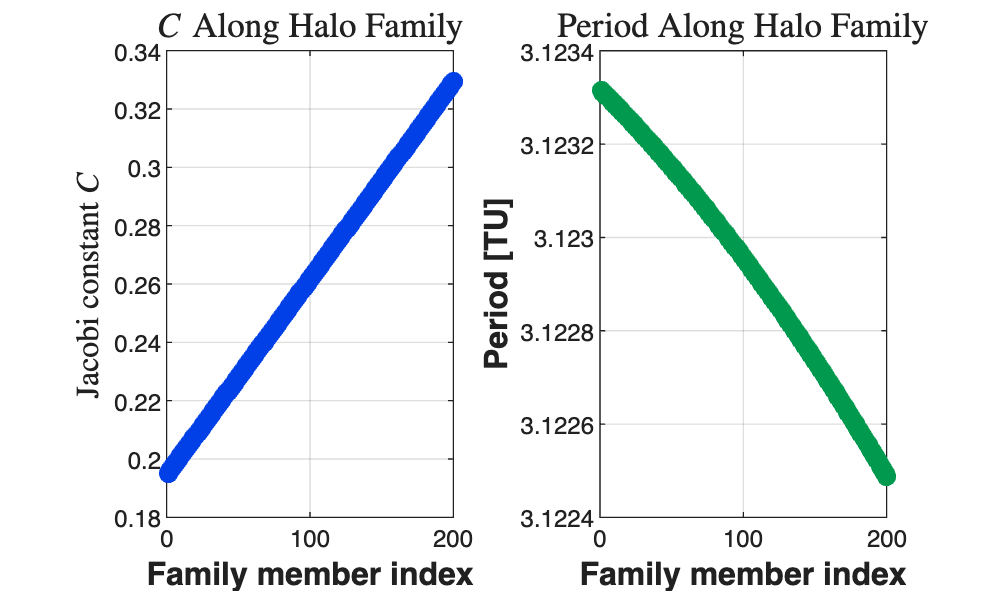

figure('Color','w');

subplot(1,2,1);
hold on; grid on; box on;
plot(1:nFam, Cvals, 'o-', 'LineWidth', 1.2, 'MarkerSize', 6, 'Color', clr.family1);
xlabel('Family member index', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Jacobi constant $C$', 'Interpreter', 'latex', 'FontSize', 12, 'FontWeight', 'bold');
title('$C$ Along Halo Family', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');

subplot(1,2,2);
hold on; grid on; box on;
plot(1:nFam, Tvals, 'o-', 'LineWidth', 1.2, 'MarkerSize', 6, 'Color', clr.family2);
xlabel('Family member index', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Period [TU]', 'FontSize', 12, 'FontWeight', 'bold');
title('Period Along Halo Family', 'Interpreter', 'latex', 'FontSize', 13, 'FontWeight', 'bold');

## Monodromy matrix and stability

For a periodic orbit of period $T$, the monodromy matrix is


$$M = \Phi(T,0)$$


Its eigenvalues are the Floquet multipliers. In Hamiltonian systems they appear in reciprocal pairs, and unstable directions generate invariant manifolds.

M_seed1 = astro.cr3bp.monodromyMatrix(seed1.state, seed1.period, muHalo);
stabSeed1 = astro.cr3bp.stabilityIndices(M_seed1);

disp('Monodromy matrix for first halo seed:');

Monodromy matrix for first halo seed:


disp(M_seed1);

   1.0e+03 *

    0.0901    0.1435    0.2642   -0.0126    0.2075    0.1815
    0.5496    0.6148    0.7188   -0.2075    0.8695    0.3055
   -0.3133   -0.2291    0.0133    0.1815   -0.3055    0.2041
    0.7986    0.8451    0.8802   -0.3249    1.1894    0.2978
    0.2042    0.1491   -0.0089   -0.1184    0.1997   -0.1338
   -0.5573   -0.5196   -0.3671    0.2642   -0.7188    0.0133




disp('Stability indices for first halo seed:');

Stability indices for first halo seed:


disp(stabSeed1);

               eigvals: [6×1 double]
               eigvecs: [6×6 double]
        spectralRadius: 486.8094
    unstableMultiplier: 3.0215e+02 + 3.8169e+02i
      stableMultiplier: 0.0013 + 0.0016i
            centerPair: [2×1 double]
              unitPair: [2×1 double]
                    nu: 1.5108e+02 + 1.9084e+02i
        classification: 'complex unstable'
           idxUnstable: 1
             idxStable: 3
             idxCenter: [2×1 double]
               idxUnit: [2×1 double]
         modulusSorted: [6×1 double]



## Invariant manifolds from halo subspaces

For halo orbits, the stable and unstable eigendirections may be complex. In that case, it is more appropriate to work with the 2D stable and unstable subspaces spanned by the real and imaginary parts of the corresponding eigenvectors.

Your function `haloManifoldSeeds`:

- computes the monodromy eigensystem

- extracts the stable and unstable subspaces

- transports them along the orbit with the STM

- builds local rings of seeds around the orbit

These ring seeds are then propagated with `propagateManifold` to visualise the stable and unstable manifold tubes.

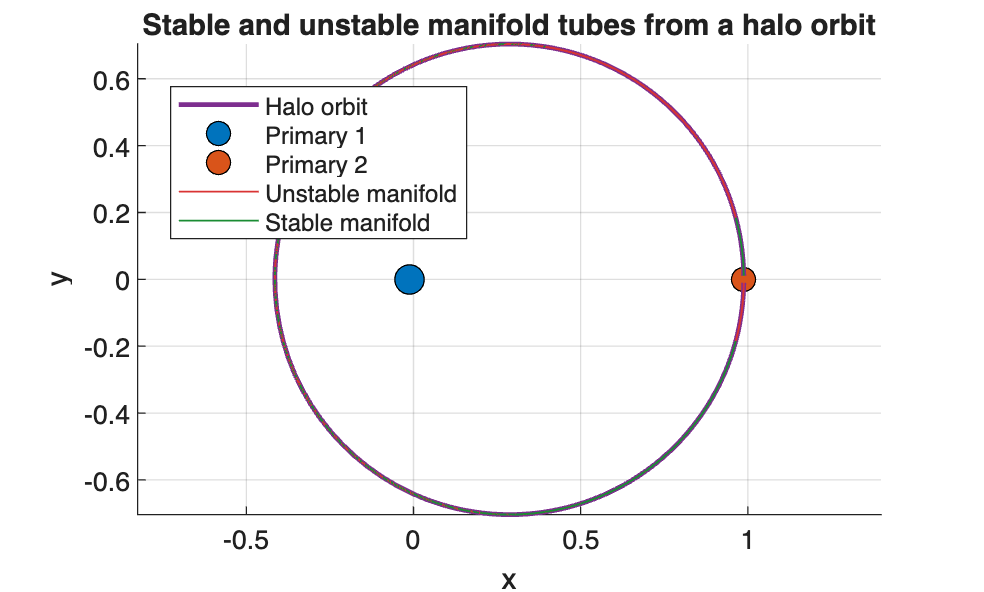

if showManifolds
    xMan = seed1.state;
    TMan = seed1.period;

    nPhaseMan  = 20;
    nCircleMan = 12;
    epsMan     = 1e-7;

    seeds = astro.cr3bp.haloManifoldSeeds( ...
        xMan, TMan, muHalo, nPhaseMan, nCircleMan, epsMan);

    tManU = 3.0;
    tManS = -3.0;

    outHaloRef = astro.propagators.propagate( ...
        @(t,x) astro.cr3bp.eomCR3BP(t, x, muHalo), ...
        [0 TMan], xMan, optsCR3BP);

    figure('Color','w');
    hold on; grid on; axis equal;

    hHalo = plot3(outHaloRef.x(:,1), outHaloRef.x(:,2), outHaloRef.x(:,3), ...
        'Color', clr.purple, 'LineWidth', 1.8);

    unstableHandle = [];
    stableHandle = [];

    for k = 1:numel(seeds)
        XU = seeds(k).xUnstableRing;
        XS = seeds(k).xStableRing;

        for j = 1:size(XU,2)
            outU = astro.cr3bp.propagateManifold(XU(:,j), tManU, muHalo);
            hU = plot3(outU.x(:,1), outU.x(:,2), outU.x(:,3), ...
                'Color', clr.manU, 'LineWidth', 0.7);
            if isempty(unstableHandle)
                unstableHandle = hU;
            end
        end

        for j = 1:size(XS,2)
            outS = astro.cr3bp.propagateManifold(XS(:,j), tManS, muHalo);
            hS = plot3(outS.x(:,1), outS.x(:,2), outS.x(:,3), ...
                'Color', clr.manS, 'LineWidth', 0.7);
            if isempty(stableHandle)
                stableHandle = hS;
            end
        end
    end

    hP1 = plot3(-muHalo, 0, 0, 'o', 'MarkerSize', 11, ...
        'MarkerFaceColor', clr.primary, 'MarkerEdgeColor', 'k');
    hP2 = plot3(1-muHalo, 0, 0, 'o', 'MarkerSize', 9, ...
        'MarkerFaceColor', clr.secondary, 'MarkerEdgeColor', 'k');

    xlabel('x');
    ylabel('y');
    zlabel('z');
    title('Stable and unstable manifold tubes from a halo orbit');
    legend([hHalo, hP1, hP2, unstableHandle, stableHandle], ...
        'Halo orbit', 'Primary 1', 'Primary 2', 'Unstable manifold', 'Stable manifold', ...
        'Location', 'best');
end

## Poincare section example

A Poincare section records intersections of trajectories with a chosen hypersurface. Here we use the plane


$$x = x_{section}$$


and collect crossings from unstable manifold seeds.

if showPoincare
    xSection = 1.05;
    direction = +1;
    tMaxSection = 4.0;

    if ~showManifolds
        xMan = seed1.state;
        TMan = seed1.period;
        nPhaseMan  = 20;
        nCircleMan = 12;
        epsMan     = 1e-7;

        seeds = astro.cr3bp.haloManifoldSeeds( ...
            xMan, TMan, muHalo, nPhaseMan, nCircleMan, epsMan);
    end

    seedMat = [];
    for k = 1:numel(seeds)
        seedMat = [seedMat, seeds(k).xUnstableRing]; %#ok<AGROW>
    end

    section = astro.cr3bp.collectPoincareSection( ...
        seedMat, tMaxSection, muHalo, xSection, direction);

    if ~isempty(section.points)
        figure('Color','w');
        hold on; grid on; box on;
        plot(section.points(2,:), section.points(5,:), 'o', ...
            'MarkerFaceColor', clr.family1, ...
            'MarkerEdgeColor', 'k', ...
            'MarkerSize', 6);
        xlabel('$y$', 'Interpreter', 'latex', 'FontSize', 12, 'FontWeight', 'bold');
        ylabel('$\dot{y}$', 'Interpreter', 'latex', 'FontSize', 12, 'FontWeight', 'bold');
        title(sprintf('Poincare section at x = %.3f', xSection), ...
            'FontSize', 14, 'FontWeight', 'bold');
    else
        fprintf('\nNo manifold trajectories hit the requested Poincare section.\n');
    end
end


No manifold trajectories hit the requested Poincare section.


## Future implementations:

- Improving multiple shooting and manifold generation;

- Validating against real missions (e.g. Artemis 1) and existing databases of periodic orbits (e.g. Howell, Restrepo)

- Adding more interactive visualisations, such as rotating/inertial frame;

- Automating initial conditions retrieval from JPL database.